# In der Dokumentation verwendete Darstellungen für die Simulation vorgegebener Batterien

## 1.1.) Neuer Leistungsverlauf mit Einsatz vorgegebener Batterien (schnelles Entladen)

% Nun sollen noch die neuen Leistungsverläufe der Strecken mit den
% ursprünglich simulierten Leistungen verglichen werden. Zusätzlich wird
% ebenfalls der Batteriestand dargestellt.
fnStr = fieldnames(BatSpecFast);

for n = 1:numel(fnStr)
    for k = 1:length(Leistung)
        figure()
        set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])
        hold on
        yyaxis left
        plot(BatSpecFast.(fnStr{n}).time, BatSpecFast.(fnStr{n}).Leistung/1000)
        plot(BatSpecFast.(fnStr{n}).time, BatSpecFast.(fnStr{n}).("LeistungNeu" + string(Leistung(k))+"kW")/1000)
        plot(BatSpecFast.(fnStr{n}).time, BatSpecFast.(fnStr{n}).("LeistungNeuRech" + string(Leistung(k))+"kW")/1000, 'LineWidth', 1)
        ylabel('Leistung [MW]')
        yyaxis right
        plot(BatSpecFast.(fnStr{n}).time, BatSpecFast.(fnStr{n}).("EBat" + string(Energie(k))+"kWh"))
        plot(BatSpecFast.(fnStr{n}).time, BatSpecFast.(fnStr{n}).("EBatRech" + string(Energie(k))+"kWh"))
        legend('Sim. Leistung', 'PBat: ' + string(Leistung(k)) + 'kW ohne Laden', 'PBat: ' + string(Leistung(k)) + 'kW mit Laden', 'EBat: ' + string(Energie(k)) + 'kWh ohne Laden' , 'EBat: ' + string(Energie(k)) + 'kWh mit Laden')
        grid()
        ylim([0, Energie(k)])
        xlabel('Fahrtzeit')
        ylabel('Batterieladestand [kW]')
        title('Leistungsverlauf mit vorgegebener Batterie auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
        subtitle('Batterie: ' + string(k) + ' mit Methode: schnelles Laden')

        % speichern der plots
        savename = "Bat_" + string(Leistung(k)) + "kW_" + fnStr(n);
        filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\schnelles_Entladen\Neuer_Leistungsverlauf', savename +'.png');
        exportgraphics(gcf, filename, 'Resolution',300)

    end
end


## 1.2.) Gesamtleistung und 8 Min. Mittelwert mit Batterieeinsatz (schnelles Entladen)

% Berechnung der 8Min Mittelwerte für die neue Leistung mit Batterie:
P_totSimMean = zeros(288,1);
P_totSimBatFastMean = zeros(288, 1);
for k = 1:2       
    if(k == 1)
        n = 1;
        for i = 1:3000:864000
            if (i < 4800)
                P_totSimMean(n,1) = mean(P_totSim(1:i));
            else
                P_totSimMean(n,1) = mean(P_totSim(i-4800:i));
            end
            n = n + 1;
        end
    else
        for z = 1:width(P_totSimBatFast)
            n = 1;
            for i = 1:3000:864000
                if (i < 4800)
                    P_totSimBatFastMean(n,z) = mean(P_totSimBatFast(1:i,z));
                else
                     P_totSimBatFastMean(n,z) = mean(P_totSimBatFast(i-4800:i,z));
                end
                n = n + 1;
            end
        end
    end
end

% Darstellung und Vergleich der Gesamtleistungen über einen Tag:
for n = 1:length(Leistung)
    figure
    t = tiledlayout(2,1);
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])

    nexttile
    hold on
    plot(time(215000:230000), P_totSim(215000:230000)/1000)
    plot(time(215000:230000), P_totSimBatFast(215000:230000,n)/1000)
    plot(time(215000:230000), P_totSimBatFast(215000:230000,n+length(Leistung))/1000)
    hold off
    legend('Sim. Leistung','PBat: ' + string(Leistung(n)) + 'kW ohne Laden', 'PBat: ' + string(Leistung(n)) + 'kW mit Laden', 'FontSize', 6.5)
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    grid()
    title('Leistungsverläufe mit vorgegebenen Batterien mit Methode schnelles Laden')
    subtitle('Vergleich der neuen Gesamtleistungen')

    % Vergleich der 8 Min Mittelwerte zwischen Messung und Messdaten der SBB
    % Erstellung eines Zeitarrays für die 5 min. Mittelwerte (alle 5 Min.)
    nexttile
    hold on
    plot(time2(70:115), P_totSimMean(70:115)/1000)
    plot(time2(70:115), P_totSimBatFastMean(70:115,n)/1000)
    plot(time2(70:115), P_totSimBatFastMean(70:115,n+length(Leistung))/1000)
    hold off
    subtitle('Vergleich der 8 Min. Mittelwerte mit vorgegebener Batterie')
    grid()
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')

    %speichern der plots
    savename = "Bat_" + string(n) + "_" + string(Leistung(n)) + "kW_Bat_Vergleich_Gesamtleistung_und_8Min_Mittelwerte";
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\schnelles_Entladen\Gesamtleistung_und_8Min_Mittelwert', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
end


## 1.3.) Reduktion der Leistungsspitzen mit vorgegebenen Batterien (schnelles Entladen)

PMax_BatSim = [];
label = string(1:length(Leistung));

for n = 1:length(Leistung)

    PMax_BatSim = [PMax_BatSim; max(P_totSimBatFast(:,n)), max(P_totSimBatFast(:,n+length(Leistung)))];

end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(PMax_BatSim/1000)
yline(max(P_totSim)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
ylim([0,max(P_totSim)/1000+4])
legend('ohne Laden', 'mit Laden')
xlabel('Batterie Nr.')
ylabel('max. Leistungsspitze [MW]')
title('Vergleich der Leistungsspitzen der Gesamtleistung mit vorgegebenen Batterien')
subtitle('Methode: schnelles Entladen')
grid()

%speichern der plots
savename = "Reduktion_max_Leistungsspitze_der_Gesamtleistung";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\schnelles_Entladen\Reduktion_Leistungsspitzen', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

PMax_BatSim = [];
label = string(1:length(Leistung));

for n = 1:length(Leistung)

    PMax_BatSim = [PMax_BatSim; max(P_totSimBatFastMean(:,n)), max(P_totSimBatFastMean(:,n+length(Leistung)))];

end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(PMax_BatSim/1000)
yline(max(P_totSimMean)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
ylim([0,max(P_totSimMean)/1000+2])
legend('ohne Laden', 'mit Laden')
xlabel('Batterie Nr.')
ylabel('max. Leistungsspitze [MW]')
title('Vergleich der Leistungsspitzen der 8 Min. Mittelwerte mit vorgegebenen Batterien')
subtitle('Methode: schnelles Entladen')
grid()

%speichern der plots
savename = "Reduktion_max_Leistungsspitze_der_8Min_Mittelwerte";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\schnelles_Entladen\Reduktion_Leistungsspitzen', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

## 2.1.) Neuer Leistungsverlauf mit Einsatz vorgegebener Batterien (Kontinuierlich)

% Nun sollen noch die neuen Leistungsverläufe der Strecken mit den
% ursprünglich simulierten Leistungen verglichen werden. Zusätzlich wird
% ebenfalls der Batteriestand dargestellt.
fnStr = fieldnames(BatSpecCont);

for n = 1:numel(fnStr)
    for k = 1:length(Leistung)
        figure()
        set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])
        hold on
        yyaxis left
        plot(BatSpecCont.(fnStr{n}).time, BatSpecCont.(fnStr{n}).Leistung/1000)
        plot(BatSpecCont.(fnStr{n}).time, BatSpecCont.(fnStr{n}).("LeistungNeu" + string(Leistung(k))+"kW")/1000)
        plot(BatSpecCont.(fnStr{n}).time, BatSpecCont.(fnStr{n}).("LeistungNeuRech" + string(Leistung(k))+"kW")/1000, 'LineWidth', 1)
        ylabel('Leistung [MW]')
        yyaxis right
        plot(BatSpecCont.(fnStr{n}).time, BatSpecCont.(fnStr{n}).("EBat" + string(Energie(k))+"kWh"))
        plot(BatSpecCont.(fnStr{n}).time, BatSpecCont.(fnStr{n}).("EBatRech" + string(Energie(k))+"kWh"))
        legend('Sim. Leistung', 'PBat: ' + string(Leistung(k)) + 'kW ohne Laden', 'PBat: ' + string(Leistung(k)) + 'kW mit Laden', 'EBat: ' + string(Energie(k)) + 'kWh ohne Laden' , 'EBat: ' + string(Energie(k)) + 'kWh mit Laden')
        grid()
        ylim([0, Energie(k)])
        xlabel('Fahrtzeit')
        ylabel('Batterieladestand [kW]')
        title('Leistungsverlauf mit vorgegebener Batterie auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
        subtitle('Batterie: ' + string(k) + ' mit Methode: Kontinuierlich')

        % speichern der plots
        savename = "Bat_" + string(Leistung(k)) + "kW_" + fnStr(n);
        filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Kontinuierlicher_Ansatz\Neuer_Leistungsverlauf', savename +'.png');
        exportgraphics(gcf, filename, 'Resolution',300)

    end
end




## 2.2.) Gesamtleistung und 8 Min. Mittelwert mit Batterieeinsatz (Kontinuierlich)

% Berechnung der 8Min Mittelwerte für die neue Leistung mit Batterie:
P_totSimMean = zeros(288,1);
P_totSimBatContMean = zeros(288, 1);
for k = 1:2       
    if(k == 1)
        n = 1;
        for i = 1:3000:864000
            if (i < 4800)
                P_totSimMean(n,1) = mean(P_totSim(1:i));
            else
                P_totSimMean(n,1) = mean(P_totSim(i-4800:i));
            end
            n = n + 1;
        end
    else
        for z = 1:width(P_totSimBatCont)
            n = 1;
            for i = 1:3000:864000
                if (i < 4800)
                    P_totSimBatContMean(n,z) = mean(P_totSimBatCont(1:i,z));
                else
                     P_totSimBatContMean(n,z) = mean(P_totSimBatCont(i-4800:i,z));
                end
                n = n + 1;
            end
        end
    end
end

% Darstellung und Vergleich der Gesamtleistungen über einen Tag:
for n = 1:length(Leistung)
    figure
    t = tiledlayout(2,1);
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])

    nexttile
    hold on
    plot(time(215000:230000), P_totSim(215000:230000)/1000)
    plot(time(215000:230000), P_totSimBatCont(215000:230000,n)/1000)
    plot(time(215000:230000), P_totSimBatCont(215000:230000,n+length(Leistung))/1000)
    hold off
    legend('Sim. Leistung','PBat: ' + string(Leistung(n)) + 'kW ohne Laden', 'PBat: ' + string(Leistung(n)) + 'kW mit Laden', 'FontSize', 6.5)
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    grid()
    title('Leistungsverläufe mit vorgegebenen Batterien mit Kontinuierlicher Methode')
    subtitle('Vergleich der neuen Gesamtleistungen')

    % Vergleich der 8 Min Mittelwerte zwischen Messung und Messdaten der SBB
    % Erstellung eines Zeitarrays für die 5 min. Mittelwerte (alle 5 Min.)
    nexttile
    hold on
    plot(time2(70:115), P_totSimMean(70:115)/1000)
    plot(time2(70:115), P_totSimBatContMean(70:115,n)/1000)
    plot(time2(70:115), P_totSimBatContMean(70:115,n+length(Leistung))/1000)
    hold off
    subtitle('Vergleich der 8 Min. Mittelwerte mit vorgegebener Batterie')
    grid()
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')

    %speichern der plots
    savename = "Bat_" + string(n) + "_" + string(Leistung(n)) + "kW_Bat_Vergleich_Gesamtleistung_und_8Min_Mittelwerte";
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Kontinuierlicher_Ansatz\Gesamtleistung_und_8Min_Mittelwert', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
end



## 2.3.) Reduktion der Leistungsspitzen mit vorgegebenen Batterien (Kontinuierlicher Ansatz)

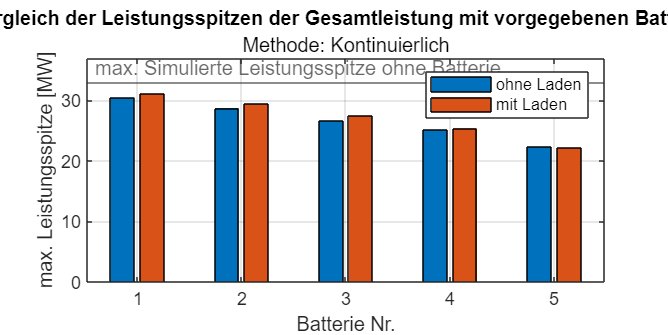

PMax_BatSim = [];
label = string(1:length(Leistung));

for n = 1:length(Leistung)

    PMax_BatSim = [PMax_BatSim; max(P_totSimBatCont(:,n)), max(P_totSimBatCont(:,n+length(Leistung)))];

end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(PMax_BatSim/1000)
yline(max(P_totSim)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
ylim([0,max(P_totSim)/1000+4])
legend('ohne Laden', 'mit Laden')
xlabel('Batterie Nr.')
ylabel('max. Leistungsspitze [MW]')
title('Vergleich der Leistungsspitzen der Gesamtleistung mit vorgegebenen Batterien')
subtitle('Methode: Kontinuierlich')
grid()

%speichern der plots
savename = "Reduktion_max_Leistungsspitze_der_Gesamtleistung";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Kontinuierlicher_Ansatz\Reduktion_Leistungsspitzen', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

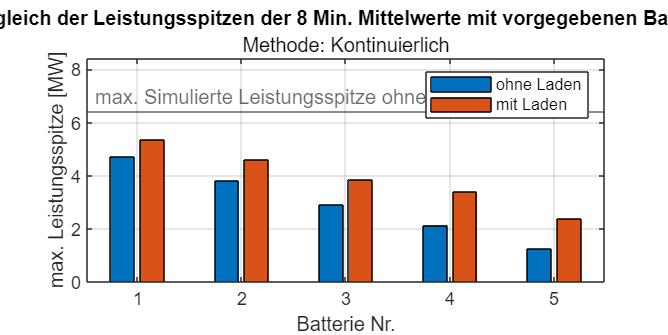


PMax_BatSim = [];
label = string(1:length(Leistung));

for n = 1:length(Leistung)

    PMax_BatSim = [PMax_BatSim; max(P_totSimBatContMean(:,n)), max(P_totSimBatContMean(:,n+length(Leistung)))];

end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(PMax_BatSim/1000)
yline(max(P_totSimMean)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
ylim([0,max(P_totSimMean)/1000+2])
legend('ohne Laden', 'mit Laden')
xlabel('Batterie Nr.')
ylabel('max. Leistungsspitze [MW]')
title('Vergleich der Leistungsspitzen der 8 Min. Mittelwerte mit vorgegebenen Batterien')
subtitle('Methode: Kontinuierlich')
grid()

%speichern der plots
savename = "Reduktion_max_Leistungsspitze_der_8Min_Mittelwerte";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Kontinuierlicher_Ansatz\Reduktion_Leistungsspitzen', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

## 3.1.) Neuer Leistungsverlauf mit Einsatz vorgegebener Batterien (Peak)

% Nun sollen noch die neuen Leistungsverläufe der Strecken mit den
% ursprünglich simulierten Leistungen verglichen werden. Zusätzlich wird
% ebenfalls der Batteriestand dargestellt.
fnStr = fieldnames(BatSpecPeak);

for n = 1:7%numel(fnStr)
    for k = 4:4%1:length(Leistung)
        figure()
        set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])
        hold on
        yyaxis left
        plot(BatSpecPeak.(fnStr{n}).time, BatSpecPeak.(fnStr{n}).Leistung/1000)
        plot(BatSpecPeak.(fnStr{n}).time, BatSpecPeak.(fnStr{n}).("LeistungNeu" + string(Leistung(k))+"kW")/1000)
        plot(BatSpecPeak.(fnStr{n}).time, BatSpecPeak.(fnStr{n}).("LeistungNeuRech" + string(Leistung(k))+"kW")/1000, 'LineWidth', 1)
        ylabel('Leistung [MW]')
        yyaxis right
        plot(BatSpecPeak.(fnStr{n}).time, BatSpecPeak.(fnStr{n}).("EBat" + string(Energie(k))+"kWh"))
        plot(BatSpecPeak.(fnStr{n}).time, BatSpecPeak.(fnStr{n}).("EBatRech" + string(Energie(k))+"kWh"))
        legend('Sim. Leistung', 'PBat: ' + string(Leistung(k)) + 'kW ohne Laden', 'PBat: ' + string(Leistung(k)) + 'kW mit Laden', 'EBat: ' + string(Energie(k)) + 'kWh ohne Laden' , 'EBat: ' + string(Energie(k)) + 'kWh mit Laden', 'location', 'southwest')
        grid()
        ylim([0, Energie(k)])
        xlabel('Fahrtzeit')
        ylabel('Batterieladestand [kW]')
        title('Leistungsverlauf mit vorgegebener Batterie auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
        subtitle('Batterie: ' + string(k) + ' mit Methode: Peak-Shaving')

        % speichern der plots
        savename = "Bat_" + string(Leistung(k)) + "kW_" + fnStr(n);
        filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Peak_Shaving_Ansatz\Neuer_Leistungsverlauf', savename +'.png');
        exportgraphics(gcf, filename, 'Resolution',300)

    end
end



## 3.1.2.) Neuer Leistungsverlauf mit Einsatz weiterer Batterie (Peak)

% Nun sollen noch die neuen Leistungsverläufe der Strecken mit den
% ursprünglich simulierten Leistungen verglichen werden. Zusätzlich wird
% ebenfalls der Batteriestand dargestellt.
fnStr = fieldnames(BatSpecPeak2);

for n = 1:numel(fnStr)
    for k = 1:length(Leistung)
        figure()
        set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])
        hold on
        yyaxis left
        plot(BatSpecPeak2.(fnStr{n}).time, BatSpecPeak2.(fnStr{n}).Leistung/1000)
        plot(BatSpecPeak2.(fnStr{n}).time, BatSpecPeak2.(fnStr{n}).("LeistungNeu" + string(Leistung(k))+"kW")/1000)
        plot(BatSpecPeak2.(fnStr{n}).time, BatSpecPeak2.(fnStr{n}).("LeistungNeuRech" + string(Leistung(k))+"kW")/1000, 'LineWidth', 1)
        ylabel('Leistung [MW]')
        yyaxis right
        plot(BatSpecPeak2.(fnStr{n}).time, BatSpecPeak2.(fnStr{n}).("EBat" + string(Energie(k))+"kWh"))
        plot(BatSpecPeak2.(fnStr{n}).time, BatSpecPeak2.(fnStr{n}).("EBatRech" + string(Energie(k))+"kWh"))
        legend('Sim. Leistung', 'PBat: ' + string(Leistung(k)) + 'kW ohne Laden', 'PBat: ' + string(Leistung(k)) + 'kW mit Laden', 'EBat: ' + string(Energie(k)) + 'kWh ohne Laden' , 'EBat: ' + string(Energie(k)) + 'kWh mit Laden', 'location', 'southwest')
        grid()
        ylim([0, Energie(k)])
        xlabel('Fahrtzeit')
        ylabel('Batterieladestand [kW]')
        title('Leistungsverlauf mit vorgegebener Batterie auf der Strecke ' + string(extractBefore(fnStr{n},'_')) + '-' + string(extractBetween(fnStr{n},'_', 'Fahrtzeit')) + ' ' + string(extractAfter(fnStr{n},'Fahrtzeit')) + 's')
        subtitle('Zusätzliche Batterie mit Methode: Peak-Shaving')

        % speichern der plots
        savename = "Bat_" + string(Leistung(k)) + "kW_" + fnStr(n);
        filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Peak_Shaving_Ansatz\Neuer_Leistungsverlauf_Zusätzliche_Batterie', savename +'.png');
        exportgraphics(gcf, filename, 'Resolution',300)

    end
end


## 3.2.) Gesamtleistung und 8 Min. Mittelwert mit Batterieeinsatz (Peak)

% Berechnung der 8Min Mittelwerte für die neue Leistung mit Batterie:
P_totSimMean = zeros(288,1);
P_totSimBatPeakMean = zeros(288, 1);
for k = 1:2       
    if(k == 1)
        n = 1;
        for i = 1:3000:864000
            if (i < 4800)
                P_totSimMean(n,1) = mean(P_totSim(1:i));
            else
                P_totSimMean(n,1) = mean(P_totSim(i-4800:i));
            end
            n = n + 1;
        end
    else
        for z = 1:width(P_totSimBatPeak)
            n = 1;
            for i = 1:3000:864000
                if (i < 4800)
                    P_totSimBatPeakMean(n,z) = mean(P_totSimBatPeak(1:i,z));
                else
                     P_totSimBatPeakMean(n,z) = mean(P_totSimBatPeak(i-4800:i,z));
                end
                n = n + 1;
            end
        end
    end
end

% Darstellung und Vergleich der Gesamtleistungen über einen Tag:
for n = 1:length(Leistung)
    figure
    t = tiledlayout(2,1);
    set(gcf, 'units', 'centimeters', 'position', [0,0,20,12])

    nexttile
    hold on
    plot(time(215000:230000), P_totSim(215000:230000)/1000)
    plot(time(215000:230000), P_totSimBatPeak(215000:230000,n)/1000)
    plot(time(215000:230000), P_totSimBatPeak(215000:230000,n+length(Leistung))/1000)
    hold off
    legend('Sim. Leistung','PBat: ' + string(Leistung(n)) + 'kW ohne Laden', 'PBat: ' + string(Leistung(n)) + 'kW mit Laden', 'FontSize', 6.5)
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')
    grid()
    title('Leistungsverläufe mit vorgegebenen Batterien mit Peak-Shaving Methode')
    subtitle('Vergleich der neuen Gesamtleistungen')

    % Vergleich der 8 Min Mittelwerte zwischen Messung und Messdaten der SBB
    % Erstellung eines Zeitarrays für die 5 min. Mittelwerte (alle 5 Min.)
    nexttile
    hold on
    plot(time2(70:115), P_totSimMean(70:115)/1000)
    plot(time2(70:115), P_totSimBatPeakMean(70:115,n)/1000)
    plot(time2(70:115), P_totSimBatPeakMean(70:115,n+length(Leistung))/1000)
    hold off
    subtitle('Vergleich der 8 Min. Mittelwerte mit vorgegebener Batterie')
    grid()
    xlabel('Uhrzeit')
    ylabel('Leistung [MW]')

    %speichern der plots
    savename = "Bat_" + string(n) + "_" + string(Leistung(n)) + "kW_Bat_Vergleich_Gesamtleistung_und_8Min_Mittelwerte";
    filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Peak_Shaving_Ansatz\Gesamtleistung_und_8Min_Mittelwert', savename +'.png');
    exportgraphics(gcf, filename, 'Resolution',300)
end



## 3.3.) Reduktion der Leistungsspitzen mit vorgegebenen Batterien (Peak-Shaving Ansatz)

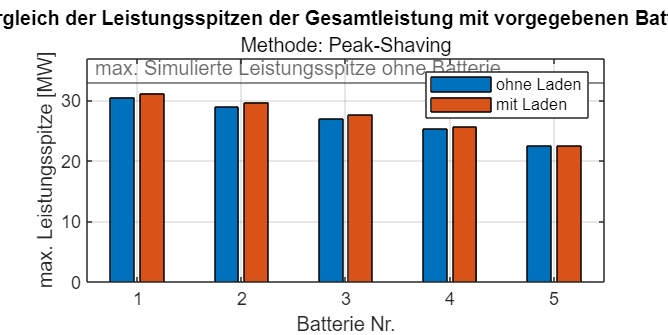

PMax_BatSim = [];
label = string(1:length(Leistung));

for n = 1:length(Leistung)

    PMax_BatSim = [PMax_BatSim; max(P_totSimBatPeak(:,n)), max(P_totSimBatPeak(:,n+length(Leistung)))];

end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(PMax_BatSim/1000)
yline(max(P_totSim)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
ylim([0,max(P_totSim)/1000+4])
legend('ohne Laden', 'mit Laden')
xlabel('Batterie Nr.')
ylabel('max. Leistungsspitze [MW]')
title('Vergleich der Leistungsspitzen der Gesamtleistung mit vorgegebenen Batterien')
subtitle('Methode: Peak-Shaving')
grid()

%speichern der plots
savename = "Reduktion_max_Leistungsspitze_der_Gesamtleistung";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Peak_Shaving_Ansatz\Reduktion_Leistungsspitzen', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

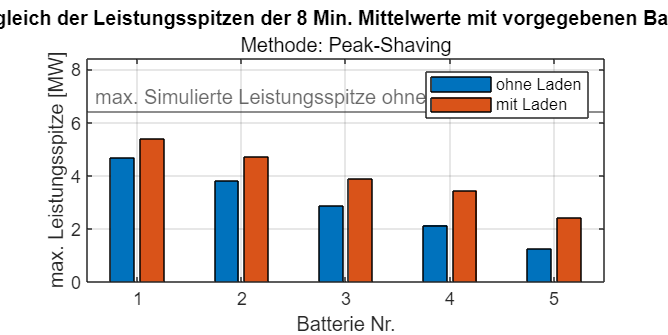


PMax_BatSim = [];
label = string(1:length(Leistung));

for n = 1:length(Leistung)

    PMax_BatSim = [PMax_BatSim; max(P_totSimBatPeakMean(:,n)), max(P_totSimBatPeakMean(:,n+length(Leistung)))];

end

figure()
set(gcf, 'units', 'centimeters', 'position', [0,0,20,10])
bar(PMax_BatSim/1000)
yline(max(P_totSimMean)/1000, '-','max. Simulierte Leistungsspitze ohne Batterie','LabelHorizontalAlignment','left')
set(gca, 'xtick', 1:length(label), 'xticklabel', label)
ylim([0,max(P_totSimMean)/1000+2])
legend('ohne Laden', 'mit Laden')
xlabel('Batterie Nr.')
ylabel('max. Leistungsspitze [MW]')
title('Vergleich der Leistungsspitzen der 8 Min. Mittelwerte mit vorgegebenen Batterien')
subtitle('Methode: Peak-Shaving')
grid()

%speichern der plots
savename = "Reduktion_max_Leistungsspitze_der_8Min_Mittelwerte";
filename = fullfile('C:\Users\Diego\switchdrive\Master of Science\P9 Master Thesis\07_Darstellung_Simulationsresultate\Simulation_vorgegebene_Batterien\Peak_Shaving_Ansatz\Reduktion_Leistungsspitzen', savename +'.png');
exportgraphics(gcf, filename, 'Resolution',300)

## Reduktion der Leistungsspitzen (Tabelle)

PRedFast = [];
PRedCont = [];
PRedPeak = [];

for n = 1:length(Leistung)

    PRedFast = [PRedFast; max(P_totSimBatFast(:,n)), max(P_totSimBatFast(:,n+length(Leistung)))];
    PRedCont = [PRedCont; max(P_totSimBatCont(:,n)), max(P_totSimBatCont(:,n+length(Leistung)))];
    PRedPeak = [PRedPeak; max(P_totSimBatPeak(:,n)), max(P_totSimBatPeak(:,n+length(Leistung)))];

end

PRed = [PRedFast, PRedCont, PRedPeak;]/1000

PRed =    30.4350   31.1016   30.4350   31.1016   30.4887   31.1554
   28.4350   29.2069   28.6894   29.3519   28.8870   29.6589
   27.6376   27.6997   26.6494   27.4087   26.8870   27.6589
   26.8339   27.0331   25.0764   25.3646   25.2941   25.6589
   25.5006   25.6997   22.2570   22.1769   22.4774   22.4274


PRedFast = [];
PRedCont = [];
PRedPeak = [];

for n = 1:length(Leistung)

    PRedFast = [PRedFast; max(P_totSimBatFastMean(:,n)), max(P_totSimBatFastMean(:,n+length(Leistung)))];
    PRedCont = [PRedCont; max(P_totSimBatContMean(:,n)), max(P_totSimBatContMean(:,n+length(Leistung)))];
    PRedPeak = [PRedPeak; max(P_totSimBatPeakMean(:,n)), max(P_totSimBatPeakMean(:,n+length(Leistung)))];

end

PRed = [PRedFast, PRedCont, PRedPeak;]/1000

PRed =     4.6647    5.3713    4.7103    5.3603    4.6834    5.3890
    3.8316    4.6667    3.8114    4.6172    3.7991    4.7251
    2.9962    3.9085    2.9024    3.8517    2.8598    3.8751
    2.2062    3.5073    2.1342    3.4128    2.1385    3.4475
    1.3310    2.5283    1.2456    2.3690    1.2549    2.4313
